# **TU: SVM classification**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

mod: 2024-2

**Gyeonheal An**

**21900416**

## Introduction

Classification with SVM

## Example: Circular Distribution

### Dataset 1:  Random Generation for Circular Distribution

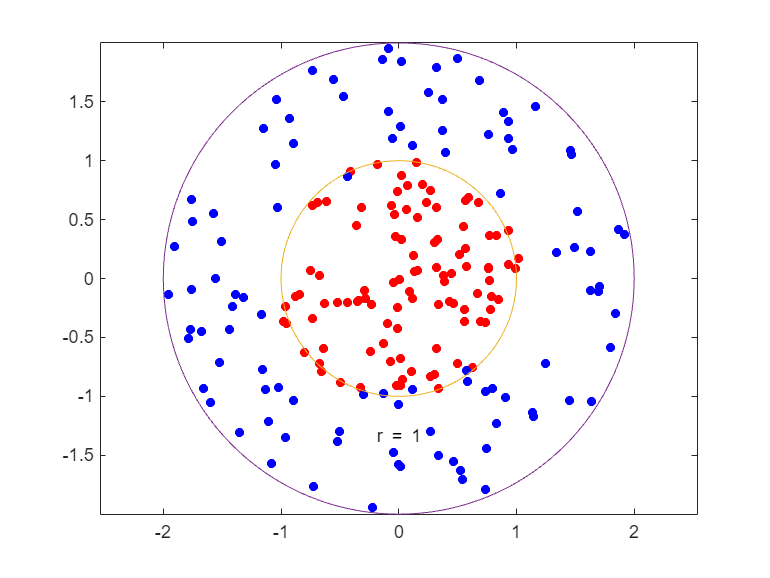

clear;

rng(1); % For reproducibility

% Class y=-1
r = sqrt(1.1*rand(100,1)); % Radius
t = 2*pi*rand(100,1);  % Angle
data1 = [r.*cos(t), r.*sin(t)]; % Points
% Class y=1
r2 = sqrt(3*rand(100,1)+0.9); % Radius
t2 = 2*pi*rand(100,1);      % Angle
data2 = [r2.*cos(t2), r2.*sin(t2)]; % points

dataC = [data1;data2];
theclass = ones(200,1);
theclass(1:100) = -1;

figure;
plot(data1(:,1),data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1),data2(:,2),'b.','MarkerSize',15)
ezpolar(@(x)1);ezpolar(@(x)2);
axis equal
hold off

### Train SVM 

% With Box Constraint =inf
cl = fitcsvm(dataC,theclass,'KernelFunction','rbf',...
    'BoxConstraint',Inf,'ClassNames',[-1,1]);


% With Box Constraint default - Also check the result
% cl = fitcsvm(dataC,theclass,'KernelFunction','rbf');

### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

mlResubErr = resubLoss(cl)

mlResubErr = 0

**Confusion matrix** on the training set

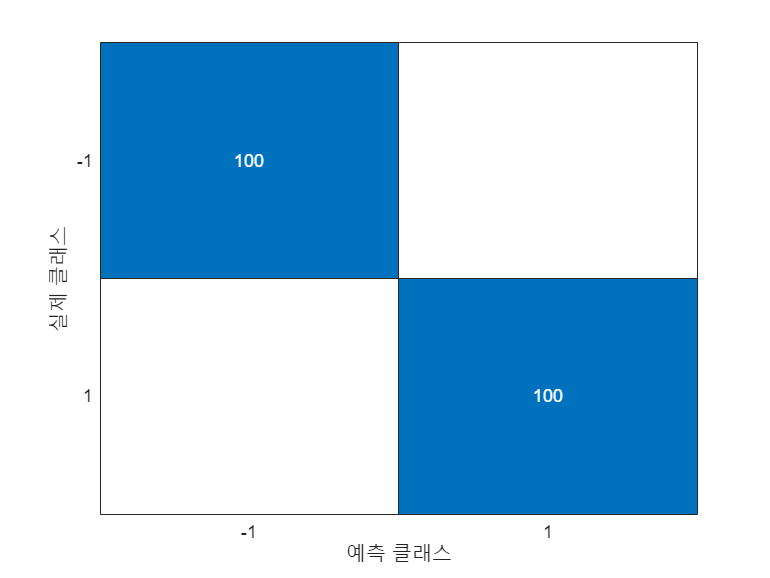

mlClass = resubPredict(cl);

figure
ldaResubCM = confusionchart(theclass,mlClass);

**Predict scores over the grid**

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(dataC(:,1)):d:max(dataC(:,1)),...
    min(dataC(:,2)):d:max(dataC(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(cl,xGrid);


**Plot the data and the decision boundary**

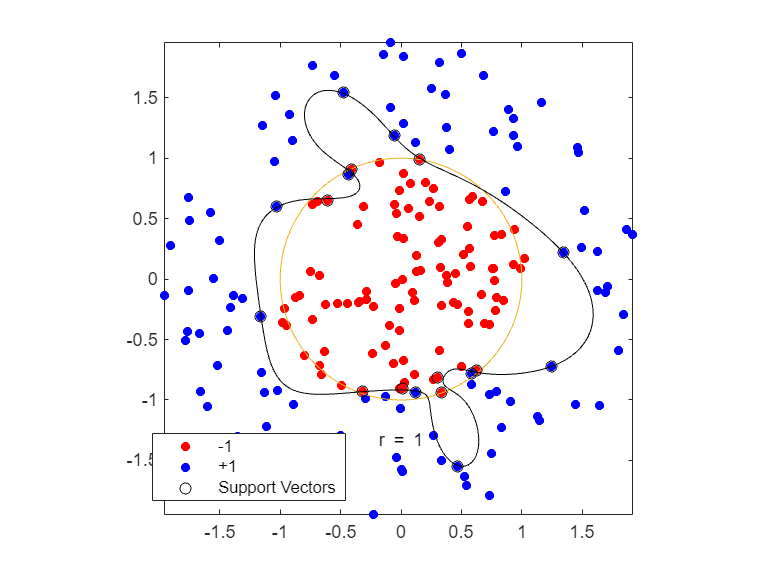

figure;
h(1:2) = gscatter(dataC(:,1),dataC(:,2),theclass,'rb','.');
hold on
ezpolar(@(x)1);
h(3) = plot(dataC(cl.IsSupportVector,1),dataC(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

rng(0)
cp = cvpartition(theclass,'KFold',10)  %k-fold

cp = K-겹 교차 검증 분할
   NumObservations: 200
       NumTestSets: 10
         TrainSize: 180  180  180  180  180  180  180  180  180  180
          TestSize: 20  20  20  20  20  20  20  20  20  20
          IsCustom: 0


cvml = crossval(cl,'CVPartition',cp);
mlCVErr = kfoldLoss(cvml)

mlCVErr = 0.0800

# Exercise  

## Exercise 1: SVM Classification with CWRU (binary class)

### Dataset :  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

- For binary class:  Outer and Inner Race Fault

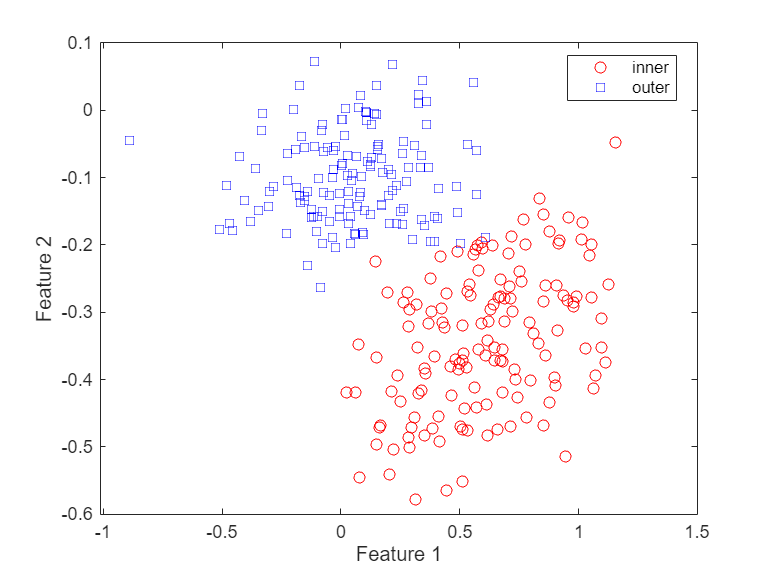

clear

% Eliminate clas 'normal'. Keep 'Inner', 'Outer'
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_train.mat");

feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));

Ytrain = class_cwru_train;       % fault class
classKeep = ~strcmp(Ytrain,'normal');
X = Xtrain(classKeep,:);
Y = Ytrain(classKeep);
N = size(X,1);

% Plot
f = figure;
gscatter(X(:,1), X(:,2), Y,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

### **CV Partition**

% cvpartition to generate k=10 disjoint stratified subsets.

%%% YOUR CODE GOES HERE
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 288
       NumTestSets: 10
         TrainSize: 260  259  259  259  259  259  259  259  259  260
          TestSize: 28  29  29  29  29  29  29  29  29  28
          IsCustom: 0

###  Train SVM 

%%% YOUR CODE GOES HERE
% specifiy class name:  fitcsvm(..., 'ClassNames',{'outer','inner'})
cl = fitcsvm(X, Y, 'ClassNames',{'outer','inner'})

cl =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'outer'  'inner'}
           ScoreTransform: 'none'
          NumObservations: 288
                    Alpha: [77×1 double]
                     Bias: -2.2185
         KernelParameters: [1×1 struct]
           BoxConstraints: [288×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [288×1 logical]
                   Solver: 'SMO'


  Properties, Methods


### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

%%% YOUR CODE GOES HERE
mlResubErr = resubLoss(cl)

mlResubErr = 0.0313

**Confusion matrix** on the training set

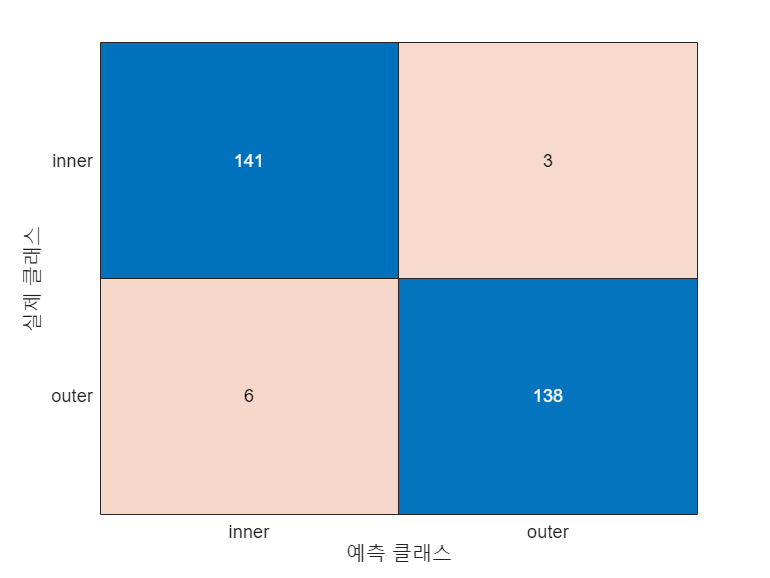

%%% YOUR CODE GOES HERE
mlClass = resubPredict(cl);

figure
ldeResubCM = confusionchart(Y, mlClass);

**Predict scores over the grid**

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)),...
    min(X(:,2)):d:max(X(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];

[~,scores] = predict(cl,xGrid)

scores =     1.5351   -1.5351
    1.6497   -1.6497
    1.7642   -1.7642
    1.8787   -1.8787
    1.9932   -1.9932
    2.1077   -2.1077
    2.2222   -2.2222
    2.3367   -2.3367
    2.4513   -2.4513
    2.5658   -2.5658


**Plot the data and the decision boundary**

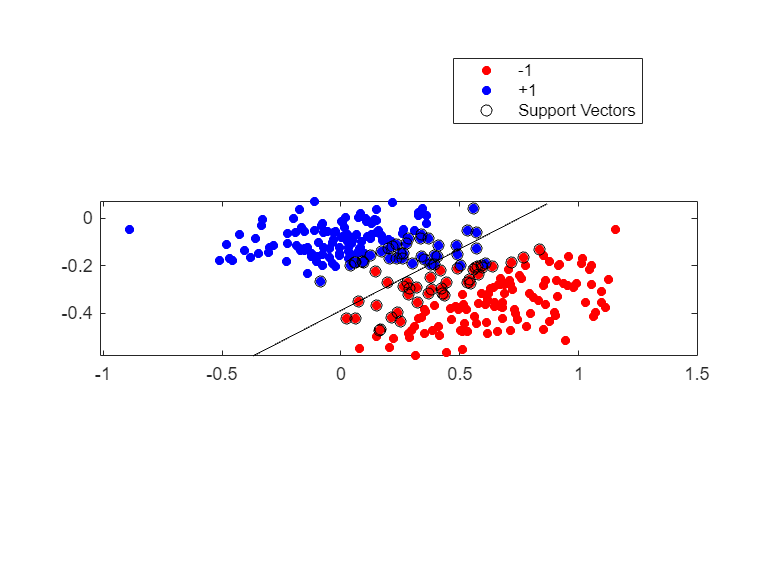

figure;
h(1:2) = gscatter(X(:,1),X(:,2),Y,'rb','.');

hold on
h(3) = plot(X(cl.IsSupportVector,1),X(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error  using 10-fold stratified cross-validation.

%%% YOUR CODE GOES HERE
rng(0)
cp = cvpartition(Y, 'KFold', 10)

cp = K-겹 교차 검증 분할
   NumObservations: 288
       NumTestSets: 10
         TrainSize: 260  259  259  259  259  259  259  259  259  260
          TestSize: 28  29  29  29  29  29  29  29  29  28
          IsCustom: 0

Cross validate and show cv loss

%%% YOUR CODE GOES HERE
cvml = crossval(cl,'CVPartition', cp)

cvml =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 288
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: {'outer'  'inner'}
         ScoreTransform: 'none'


  Properties, Methods


mlCVErr = kfoldLoss(cvml)

mlCVErr = 0.0313

## Exercise 2: SVM Classification with CWRU (3 classes)

Now, Use all 3 classes:  normal,  outer, inner.  Apply Multi_Class SVM 

**Features**

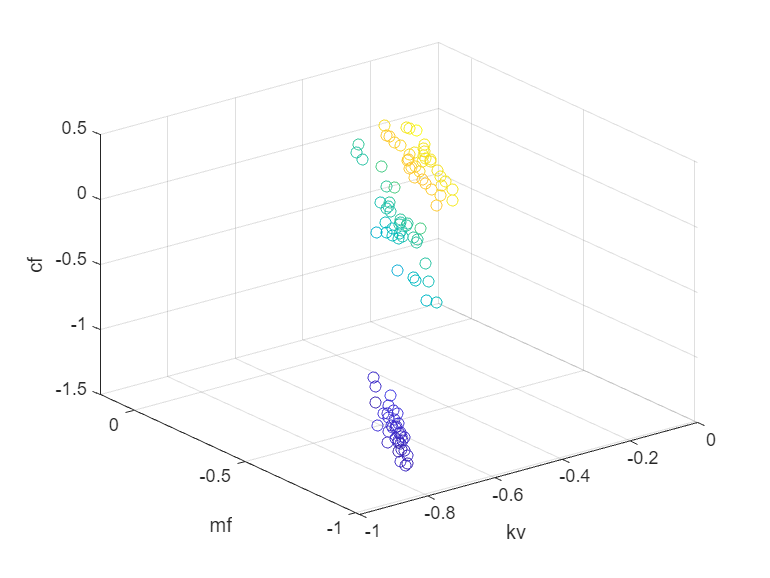

clear

load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_test.mat");

% Example
X(:, 1) = table2array(glob_all_test(:, "kv"));       % Kurtosis value of time data
X(:, 2) = table2array(glob_all_test(:, "mf"));       % Marginal-Factor
X(:, 3) = table2array(glob_all_test(:, "cf"));       % Crast-Factor

Ytrain = class_cwru_test;
Y = Ytrain;
N = size(X,1);

% Plot
f = figure;
tableX = glob_all_test(:,{'kv','mf','cf'});
scatter3(tableX,'kv','mf','cf','ColorVariable','kv');

xlabel('kv');
ylabel('mf');
zlabel('cf');

Analyze  the test and train results 

cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 108
       NumTestSets: 10
         TrainSize: 98  97  97  97  97  97  97  97  97  98
          TestSize: 10  11  11  11  11  11  11  11  11  10
          IsCustom: 0

cl = fitcecoc(X, Y, 'ClassNames',{'normal','inner','outer'})

cl =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'normal'  'inner'  'outer'}
           ScoreTransform: 'none'
           BinaryLearners: {3×1 cell}
               CodingName: 'onevsone'


  Properties, Methods


mlResubErr = resubLoss(cl)

mlResubErr = 0

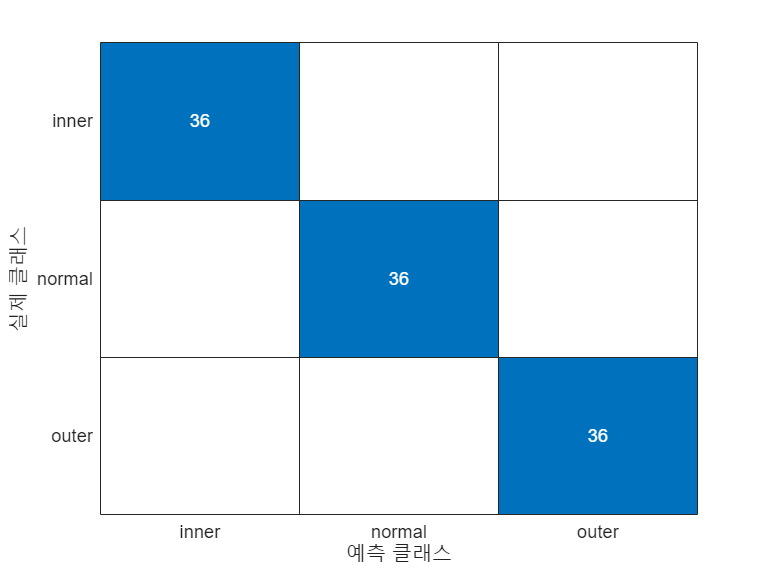

%%% YOUR CODE GOES HERE
mlClass = resubPredict(cl);

figure
ldeResubCM = confusionchart(Y, mlClass);

d = 0.02;
[x1Grid,x2Grid,x3Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)), ...
    min(X(:,2)):d:max(X(:,2)), min(X(:,3)):d:max(X(:,3)));
xGrid = [x1Grid(:),x2Grid(:), x3Grid(:)];

[~,scores] = predict(cl,xGrid)

scores =          0   -0.7114   -1.5751
         0   -0.7038   -1.5528
         0   -0.6961   -1.5305
         0   -0.6885   -1.5082
         0   -0.6809   -1.4859
         0   -0.6732   -1.4636
         0   -0.6656   -1.4413
         0   -0.6580   -1.4190
         0   -0.6503   -1.3967
         0   -0.6427   -1.3744


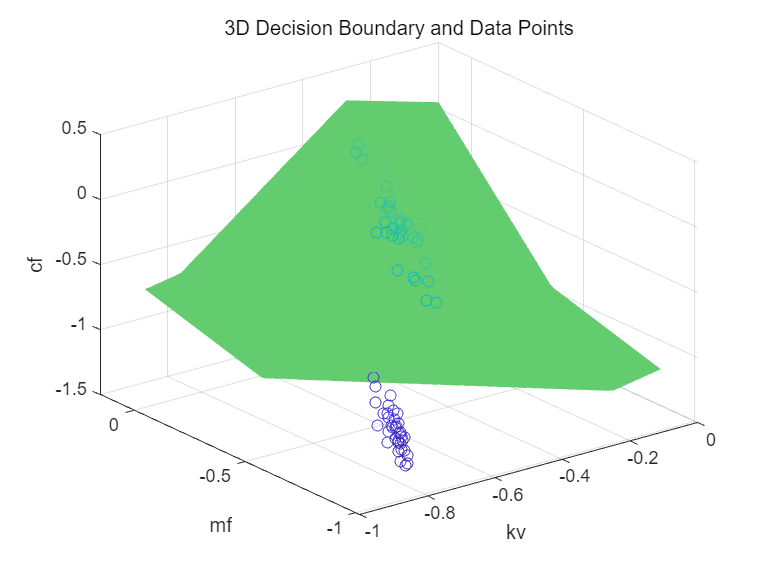

figure;
h(1:2) = scatter3(tableX,'kv','mf','cf','ColorVariable','kv');

hold on

% Reshape the scores to match the grid dimensions
scores_reshaped = reshape(scores(:, 2), size(x1Grid));
% Plot the decision boundary in 3D using isosurface
isosurface(x1Grid, x2Grid, x3Grid, scores_reshaped);
xlabel('kv');
ylabel('mf');
zlabel('cf');
title('3D Decision Boundary and Data Points');
hold off;

rng(0)
cp = cvpartition(Y, 'KFold', 10)

cp = K-겹 교차 검증 분할
   NumObservations: 108
       NumTestSets: 10
         TrainSize: 98  97  97  97  97  97  97  97  97  98
          TestSize: 10  11  11  11  11  11  11  11  11  10
          IsCustom: 0

cvml = crossval(cl,'CVPartition', cp)

cvml =   ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {'x1'  'x2'  'x3'}
           ResponseName: 'Y'
        NumObservations: 108
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: {'normal'  'inner'  'outer'}
         ScoreTransform: 'none'


  Properties, Methods


mlCVErr = kfoldLoss(cvml)

mlCVErr = 0

Compare performance of SVM with other models such as Logistic Regression